channels=5;
nBits=12;
VDD=3.3;

fid=fopen("out-2024-01-31-10.04.42.bin","rb");

nomPeriod=fread(fid,1,"double");
data=fread(fid,"uint16");

nSamples=numel(data)/channels; %Antall sampler per ADC
dataMatrix = reshape(data,channels,nSamples); %Matrise med verdiene til ADC-ene i hver rad
fclose(fid);

nomPeriod = nomPeriod * 1e-6;
n=1:nSamples;
t=n*nomPeriod;
h=transpose(hann(nSamples)); %Hanning Vindu med samme lengde som antall sampler

%Omformer matrisen til array av hver ADC, med riktig spenningsverdier
ADC1=dataMatrix(1,:)*VDD/2.^(nBits); 
ADC2=dataMatrix(2,:)*VDD/2.^(nBits);
ADC3=dataMatrix(3,:)*VDD/2.^(nBits);
ADC4=dataMatrix(4,:)*VDD/2.^(nBits);
ADC5=dataMatrix(5,:)*VDD/2.^(nBits);

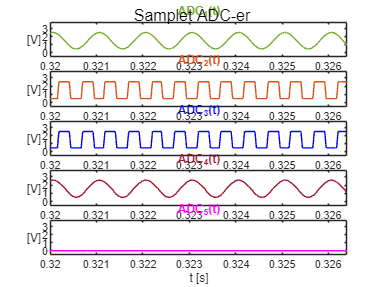

%Tidsserie
figure;
sgtitle("Samplet ADC-er")
subplot(5,1,1);
plot(t,ADC1,'color',[0.4660 0.6740 0.1880]);
ylabel("[V]"); ylim([-0.5, 3.8])
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_1(t)",'color',[0.4660 0.6740 0.1880])
set(get(gca,'ylabel'),'rotation',0);

subplot(5,1,2);
plot(t,ADC2,'color',[0.8500 0.3250 0.0980]);
ylabel("[V]"); ylim([-0.5, 3.8])
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_2(t)",'color',[0.8500 0.3250 0.0980])
set(get(gca,'ylabel'),'rotation',0);

subplot(5,1,3);
plot(t,ADC3,'color',"b");
ylabel("[V]"); ylim([-0.5, 3.8])
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_3(t)",'color',"b")
set(get(gca,'ylabel'),'rotation',0);

subplot(5,1,4);
plot(t,ADC4,'color',[0.6350 0.0780 0.1840]);
ylabel("[V]"); ylim([-0.5, 3.8])
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_4(t)",'color',[0.6350 0.0780 0.1840])
set(get(gca,'ylabel'),'rotation',0);

subplot(5,1,5);
plot(t(10000:10200),ADC5(10000:10200),'color',"m");
ylabel("[V]"); ylim([-0.5, 3.8])
xlabel("t [s]"); xlim([t(10000) t(10200)]);
title("ADC_5(t)",'color',"m")
set(get(gca,'ylabel'),'rotation',0);

N_fft=2.^(12);
A1=fftshift(fft(h.*ADC1,N_fft));
A2=fftshift(fft(h.*ADC2,N_fft));
A3=fftshift(fft(h.*ADC3,N_fft));
A4=fftshift(fft(h.*ADC4,N_fft));
A5=fftshift(fft(h.*ADC5,N_fft));
f_fft=1/(N_fft*nomPeriod)*(-N_fft/2:N_fft/2-1);

S1=20*log(abs(A1));
S2=20*log(abs(A2));
S3=20*log(abs(A3));
S4=20*log(abs(A4));
S5=20*log(abs(A5));

S1=S1-max(S1);
S2=S2-max(S2);
S3=S3-max(S3);
S4=S4-max(S4);
S5=S5-max(S5);

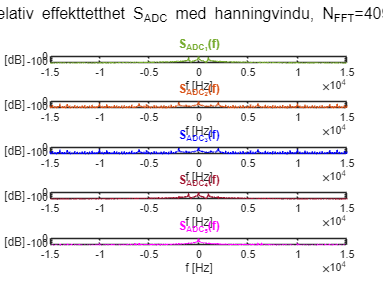

%Frekvensspekter / Effekttetthet
figure;
sgtitle("Relativ effekttetthet S_{ADC} med hanningvindu, N_{FFT}="+N_fft);
subplot(5,1,1);
plot(f_fft,S1,'color',[0.4660 0.6740 0.1880]);
ylabel("[dB]"); ylim([-150 10]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_1}(f)",'color',[0.4660 0.6740 0.1880])
set(get(gca,'ylabel'),'rotation',0);

subplot(5,1,2);
plot(f_fft,S2,'color',[0.8500 0.3250 0.0980]);
ylabel("[dB]"); ylim([-150 10]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_2}(f)",'color',[0.8500 0.3250 0.0980])
set(get(gca,'ylabel'),'rotation',0);

subplot(5,1,3);
plot(f_fft,S3,'color',"b");
ylabel("[dB]"); ylim([-150 10]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_3}(f)",'color',"b")
set(get(gca,'ylabel'),'rotation',0);

subplot(5,1,4);
plot(f_fft,S4,'color',[0.6350 0.0780 0.1840]);
ylabel("[dB]"); ylim([-150 10]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_4}(f)",'color',[0.6350 0.0780 0.1840])
set(get(gca,'ylabel'),'rotation',0);

subplot(5,1,5);
plot(f_fft,S5,'color',"m");
ylabel("[dB]"); ylim([-150 10]);
xlabel("f [Hz]"); xlim([-1.5 1.5]*10.^4);
title("S_{ADC_5}(f)",'color',"m")
set(get(gca,'ylabel'),'rotation',0);

disp(snr(ADC1));

   57.0371



disp(snr(ADC2));

   11.0358



disp(snr(ADC3));

   11.0400



disp(snr(ADC4));

   42.2581



disp(snr(ADC5));

   -6.5386

